# Skin Lesion Classification via CNN Transfer Learning

Last updated: October 2, 2021

#### Load dataset

dataLocation = "Dataset/Images_500"

dataLocation = "Dataset/Images_500"

labelsLocation = "Dataset/groundtruth_categorical.csv"

labelsLocation = "Dataset/groundtruth_categorical.csv"

Create a datastore for the raw images

image_datastore = imageDatastore(dataLocation);
num_images = length(image_datastore.Files);

Import ground truth labels

groundtruth = readtable(labelsLocation);
image_datastore.Labels = categorical(groundtruth.category(1:num_images));
disp(countEachLabel(image_datastore));

          Label          Count
    _________________    _____

    Melanocytic nevus     329 
    Melanoma              100 



Display some images with their labels

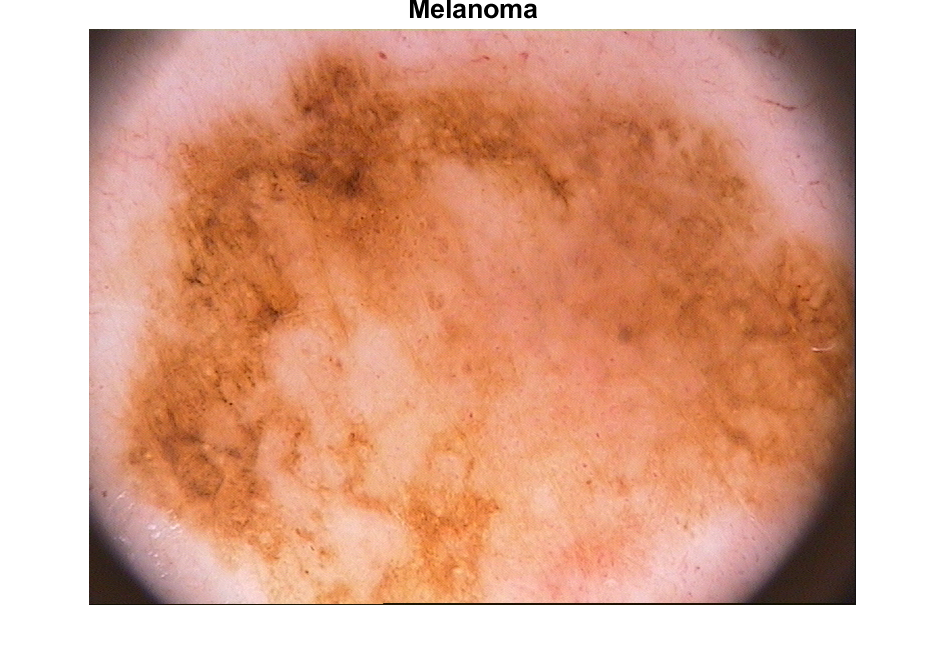

sample_idx = 280;
imshow(readimage(image_datastore, sample_idx));
title(image_datastore.Labels(sample_idx), 'FontSize', 20);

#### Split dataset into training set, validation set, and test set.

[trainImds, valImds, testImds] = splitEachLabel(image_datastore, 0.6, 0.2, 'randomized');

#### Image augmentation and regularization

trainds = augmentedImageDatastore([224,224], trainImds);
valds = augmentedImageDatastore([224,224], valImds);
testds = augmentedImageDatastore([224,224], testImds);



### Import and modify pretrained Neural Network

net = googlenet;
lgraph = layerGraph(net);

newFc = fullyConnectedLayer(2,"Name","new_fc")

newFc =   FullyConnectedLayer with properties:

          Name: 'new_fc'

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 2

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties


lgraph = replaceLayer(lgraph,"loss3-classifier",newFc)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


newOut = classificationLayer("Name","new_out")

newOut =   ClassificationOutputLayer with properties:

            Name: 'new_out'
         Classes: 'auto'
    ClassWeights: 'none'
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


lgraph = replaceLayer(lgraph,"output",newOut)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


### Set training options

Stochastic Gradient Descent with Momentum

Learning rate = 0.001

options = trainingOptions("sgdm","InitialLearnRate", 0.001);

### Train the neural network

lesionNet = trainNetwork(trainds, lgraph, options);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:15 |       30.47% |       1.9647 |          0.0010 |
|      25 |          50 |       00:11:01 |       91.41% |       0.1937 |          0.0010 |
|      30 |          60 |       00:13:12 |       99.22% |       0.1048 |          0.0010 |
|========================================================================================|


#### Evaluate network on Validation set


preds = classify(lesionNet, valds);
valTrue = valImds.Labels;
accuracy = nnz(preds == valTrue)/numel(preds)

accuracy = 0.7674

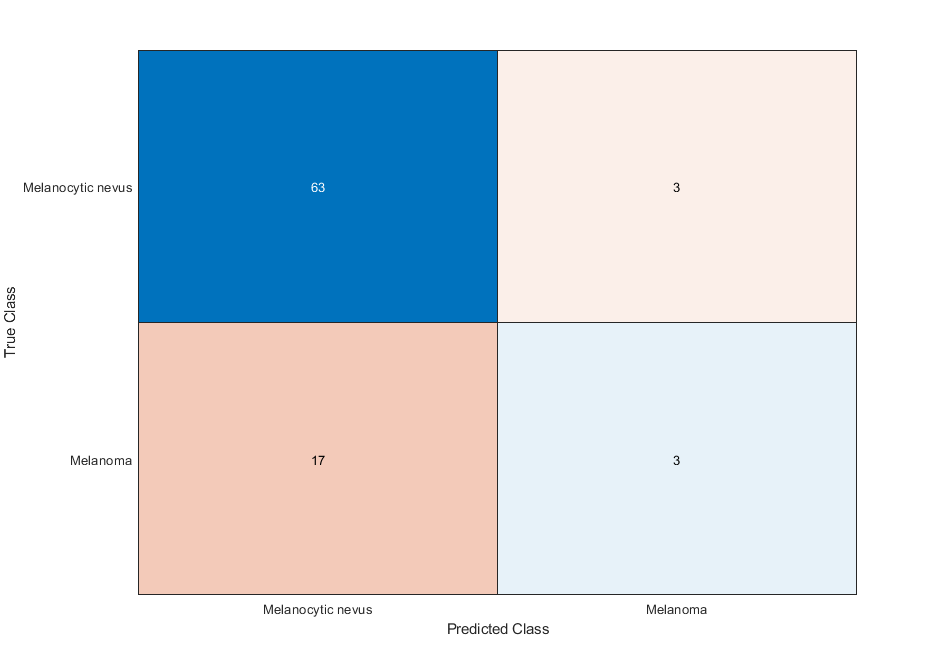


confusionchart(valTrue, preds);

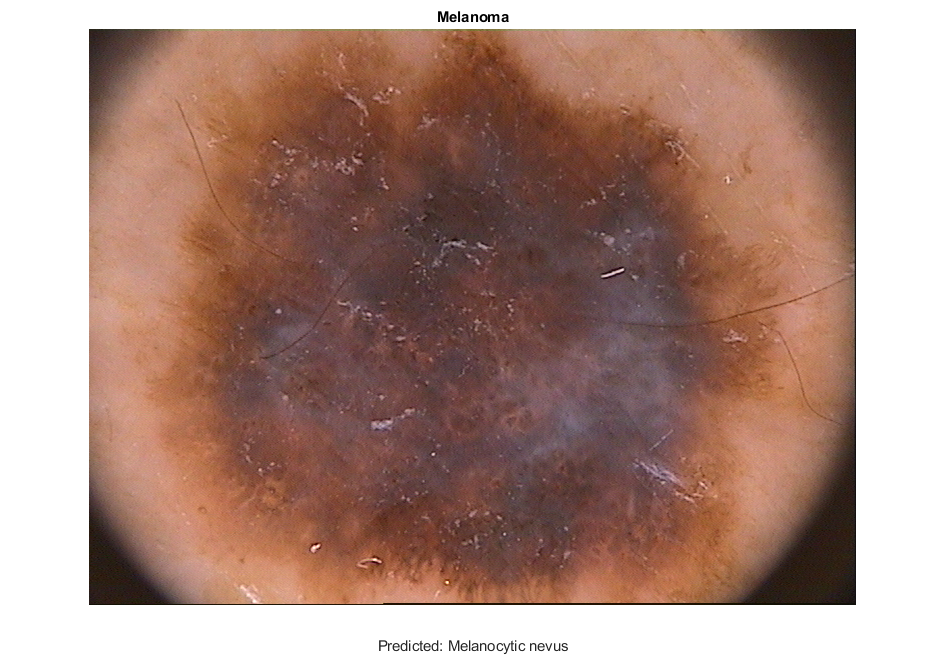

failedPredictions = find(preds~=valTrue);
num_fail = numel(failedPredictions);
failedSample = 13;
if ~isempty(failedPredictions)
    imshow(readimage(valImds,failedPredictions(failedSample)))
    title(valTrue(failedPredictions(failedSample)))
    xlabel("Predicted: " + string(preds(failedPredictions(failedSample))))
end